[~,p] = fit_logistic(time_E1,OD1)

p =   361.3000    1.1572    0.0101


t = 0:1200;
q = p(2)./(1+exp(-p(3)*(t-p(1))));
b = bar(time_E1, smell1, 'y')

b =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 0.8000
    FaceColor: [1 1 0]
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [0 23.0000 43.0000 459.0000 469 480 490.0000 503.0000 861 874.0000 886.0000 898.0000 910 923.0000 1085 1.1200e+03 1131]
        YData: [0.3333 0.3333 0 1 1 1 1.3333 0.3333 0.6667 1 1 1.6667 0.6667 1 0.5000 2 2]

  Show all properties


hold on
plot(t,q,'k');
plot(time_E1, OD1,'*','MarkerSize', 5,'MarkerEdgeColor','red');
xlabel('Time (min)')    
ylabel('OD600')
s=findobj('tag', 'legend')

s =   0×0 empty GraphicsPlaceholder array.


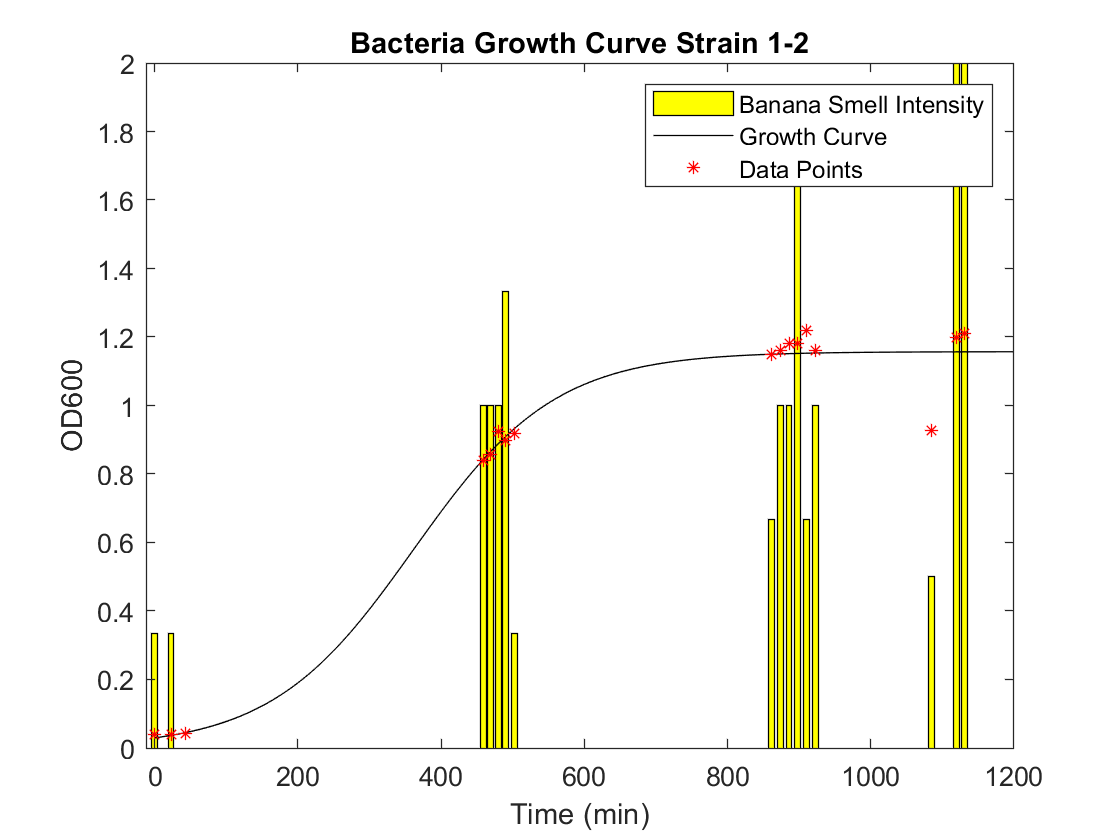


title('Bacteria Growth Curve Strain 1-2')

legend('Banana Smell Intensity','Growth Curve', 'Data Points')